## Vine Robot Animation Code

- Takes input flat q vector (all q position vectors appended)

- User specifies number of segments present in the simulation for identifying poses

- Animates through all of the poses

**Example Implementation**

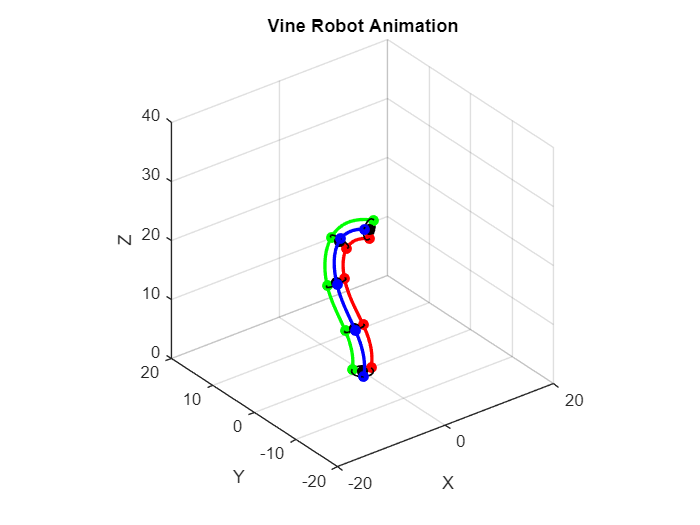

% Example implementation of animate_from_flat_function
q_flat = [4.00,4.00,4.00, 4.00,4.00,4.00, 4.00,4.00,4.00,4.00,4.00,4.00, ...
    6.95,7.44,6.12, 7.44,7.29,7.25, 4.65,7.10,7.41, 4.01,4.07,7.44, ...
    6.00,7.00,6.50, 7.00,6.50,7.00, 5.50,6.50,7.00,6.00,7.10,7.41, ...
    6.95,7.44,6.12, 7.44,7.29,7.25, 4.65,7.10,7.41, 4.01,4.07,7.44];
n = 4;  % number of segments
r_real = 5*2/pi/2; % robot radius
frame_delay = 0.4; % delay between frames in animation

animate_from_flat_q(q_flat, n, r_real, frame_delay);

**Main animation function**

- takes an appended q vector containing all poses

function animate_from_flat_q(q_flat, n, r_real, frame_delay)
    % Splits the appended q vector into individual segments and loops
    % through the animation of each

    % debugging statement for valid lengths
    values_per_config = 3 * n;
    if mod(length(q_flat), values_per_config) ~= 0
        error('Length of q_flat must be divisible by 3 * n (i.e., %d)', values_per_config);
    end
    
    % number of configurations
    num_configs = length(q_flat) / values_per_config;
    
    % split flat vector into number of individual q segments
    q_sequences = cell(1, num_configs);
    for i = 1:num_configs
        idx_start = (i - 1) * values_per_config + 1;
        idx_end = i * values_per_config;
        q_sequences{i} = q_flat(idx_start:idx_end);
    end

    % call animation function
    animate_vine_robot(q_sequences, r_real, frame_delay);
end

**Singular pose animation function with other nested helper functions**

function animate_vine_robot(q_sequences, r_real, frame_delay)
    % Animate multiple vine robot configurations given a vector of q values

    % defaults for radius and frame delay
    if nargin < 2 || isempty(r_real)
        r_real = 5*2/pi/2; 
    end
    if nargin < 3 || isempty(frame_delay)
        frame_delay = 0.5; 
    end

    % input debugging
    for i = 1:length(q_sequences)
        if mod(length(q_sequences{i}), 3) ~= 0
            error('Each q vector must have a length that is a multiple of 3');
        end
    end

    % create figure
    fig = figure;
    axis equal;
    grid on;
    xlim([-20 20]);
    ylim([-20 20]);
    zlim([0 40]);
    hold on;
    view(3);
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title('Vine Robot Animation');

    % initial visualization with first config
    h = visualize_configuration(q_sequences{1}, r_real);

    % loop the animation
    for seq_idx = 1:length(q_sequences)
        q = q_sequences{seq_idx};

        % clear previous visualization
        delete(get(gca, 'Children'));

        % update the visualization
        h = visualize_configuration(q, r_real);

        % pause between the frames
        drawnow;
        pause(frame_delay);

        % break if figure gets closed
        if ~isvalid(fig)
            break;
        end
    end
end

function h = visualize_configuration(q, r_real);
    % Create a visualization for a single configuration

    % Actuator start positions (column vectors)
    act_11_start = [r_real; 0; 0; 1];
    act_12_start = [r_real*cos(2*pi/3); r_real*sin(2*pi/3); 0; 1];
    act_13_start = [r_real*cos(4*pi/3); r_real*sin(4*pi/3); 0; 1];

    % Base coordinate system
    Base_coord = eye(4);

    % Generate transformation matrices and collect all points
    prev_T = Base_coord;
    num_segments = length(q)/3;
    all_centers = [Base_coord(1:3,4)];
    all_actuator_points = cell(3, num_segments + 1);

    % Store initial points
    all_actuator_points{1,1} = act_11_start(1:3);
    all_actuator_points{2,1} = act_12_start(1:3);
    all_actuator_points{3,1} = act_13_start(1:3);

    for seg = 1:num_segments
        q_start = (seg-1)*3 + 1;
        [T_k, act_1_end, act_2_end, act_3_end] = ...
            gen_transform(q(q_start), q(q_start+1), q(q_start+2), r_real, ...
            act_11_start, act_12_start, act_13_start, prev_T);

        prev_T = prev_T * T_k;
        all_centers(:,seg+1) = prev_T(1:3,4);

        % Store actuator endpoints
        all_actuator_points{1,seg+1} = act_1_end(1:3);
        all_actuator_points{2,seg+1} = act_2_end(1:3);
        all_actuator_points{3,seg+1} = act_3_end(1:3);
    end

    % Initialize handles structure
    h = struct();

    % Plot center points
    h.centers = plot3(all_centers(1,:), all_centers(2,:), all_centers(3,:), ...
                    '.', 'MarkerSize', 20, 'Color', 'black');

    % Draw smooth continuous curves for each actuator
    colors = ['r', 'g', 'b']; % Actuator colors
    h.actuators = gobjects(1,3);

    for act = 1:3
        % Collect all points for this actuator
        actuator_pts = zeros(3, size(all_actuator_points,2));
        for seg = 1:size(all_actuator_points,2)
            actuator_pts(:,seg) = all_actuator_points{act,seg};
        end

        % Fit a smooth spline through all points
        t = cumsum([0, sqrt(sum(diff(actuator_pts,1,2).^2,1))]);
        tt = linspace(0,t(end),100);

        xx = spline(t, actuator_pts(1,:), tt);
        yy = spline(t, actuator_pts(2,:), tt);
        zz = spline(t, actuator_pts(3,:), tt);

        % Plot the smooth curve
        h.actuators(act) = plot3(xx, yy, zz, 'Color', colors(act), 'LineWidth', 2);
    end

    % Draw cross-sections
    h.cross_sections = gobjects(1, size(all_actuator_points,2));
    h.actuator_markers = gobjects(3, size(all_actuator_points,2));

    for seg = 1:size(all_actuator_points,2)
        % Get the three actuator points for this cross-section
        P1 = all_actuator_points{1,seg};
        P2 = all_actuator_points{2,seg};
        P3 = all_actuator_points{3,seg};

        % Calculate the normal vector to the cross-section plane
        normal = cross(P2 - P1, P3 - P1);
        if norm(normal) < 1e-6
            normal = [0; 0; 1]; % Default if points are colinear
        else
            normal = normal / norm(normal);
        end

        % Calculate the center point
        center = mean([P1, P2, P3], 2);

        % Calculate radius
        radius = mean([norm(P1-center), norm(P2-center), norm(P3-center)]);

        % Create a circle in the cross-section plane
        v1 = P1 - center;
        v1 = v1 / norm(v1);
        v2 = cross(normal, v1);
        v2 = v2 / norm(v2);

        theta = linspace(0, 2*pi, 100);
        circle_points = center + radius*(v1*cos(theta) + v2*sin(theta));

        % Plot the circle
        h.cross_sections(seg) = plot3(circle_points(1,:), circle_points(2,:), circle_points(3,:), ...
                               'k-', 'LineWidth', 1);

        % Mark the actuator points on the circle
        h.actuator_markers(1,seg) = plot3(P1(1), P1(2), P1(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
        h.actuator_markers(2,seg) = plot3(P2(1), P2(2), P2(3), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 6);
        h.actuator_markers(3,seg) = plot3(P3(1), P3(2), P3(3), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 6);
    end
end

function [T_k, act_1_end, act_2_end, act_3_end, rho_k] = ...
    gen_transform(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end